% Generate Probability of Detection Code
load trainedNet

gainval = [ 0.008 0.01 0.02 0.04 0.06 0.08 0.1 0.12 0.14 0.16 0.18 0.2 0.22 0.24 0.26 0.28 0.3];
P_d_tot_arr = [];
P_d_bw_arr = [];
P_d_nn_arr = [];

for gain = gainval
    gain
    set_param('Filter_Bank_Model/Gain1','Gain','gain');
    sim('Filter_Bank_Model',100);
    
    
    % Noise + Signal power in one Filter
    sig_noise_bw = load('sig_noise_bw.mat');
    sig_noise_bw_data = sig_noise_bw.ans.Data; % Time-series data for signal
    sig_noise_bw_data = reshape(sig_noise_bw_data,[length(sig_noise_bw_data), 1]);
    
    Pd_bw = sum(sig_noise_bw_data > 8.5)/length(sig_noise_bw_data)*100
    P_d_bw_arr = [P_d_bw_arr Pd_bw];
    
    
    % Total Noise + Signal Power
    sig_noise_total = load('sig_noise.mat');
    sig_noise_total_data = sig_noise_total.ans.Data; % Time-series data for noise
    sig_noise_total_data = reshape(sig_noise_total_data,[length(sig_noise_total_data), 1]);
    
    Pd_tot = sum(sig_noise_total_data > 12)/length(sig_noise_total_data)*100
    P_d_tot_arr = [P_d_tot_arr Pd_tot];
    
    % Load IQ Data for Bandwidth Signal + Noise
    data = load('sig_noise_bw_IQ.mat');
    data = data.ans.Data;
    data = reshape(data,[size(data,1)*size(data,3) 1]);
    clip_index = rem(length(data), 1024);
    data = data(1:length(data)-clip_index);
    data = reshape(data, [1024 1 length(data)/1024]);
    data_real = real(data);
    data_imag = imag(data);
    data_sig = [data_real data_imag];
    data_sig_shaped = zeros(1,1024,2,4306);
    data_sig_shaped(:) = data_sig;
    
    
    % Predict Using Neural Network
    predLabels = trainedNet.classify(data_sig_shaped);
    P_d_nn = sum(predLabels == categorical(1))/length(predLabels)*100
    P_d_nn_arr = [P_d_nn_arr P_d_nn];
    
end

gain = 0.0080

Pd_bw = 0.2041

Pd_tot = 0.4127

P_d_nn = 19.3683

gain = 0.0100

Pd_bw = 0.2177

Pd_tot = 0.3991

P_d_nn = 20.0650

gain = 0.0200

Pd_bw = 0.2540

Pd_tot = 0.4081

P_d_nn = 22.6196

gain = 0.0400

Pd_bw = 0.3174

Pd_tot = 0.5533

P_d_nn = 36.5072

gain = 0.0600

Pd_bw = 0.5034

Pd_tot = 0.8344

P_d_nn = 61.3330

gain = 0.0800

Pd_bw = 0.9659

Pd_tot = 1.3650

P_d_nn = 85.5318

gain = 0.1000

Pd_bw = 2.2493

Pd_tot = 2.4625

P_d_nn = 98.0492

gain = 0.1200

Pd_bw = 5.0519

Pd_tot = 4.9113

P_d_nn = 99.8142

gain = 0.1400

Pd_bw = 10.9791

Pd_tot = 9.7547

P_d_nn = 100

gain = 0.1600

Pd_bw = 21.9446

Pd_tot = 18.1579

P_d_nn = 100

gain = 0.1800

Pd_bw = 39.3814

Pd_tot = 31.6358

P_d_nn = 100

gain = 0.2000

Pd_bw = 59.7660

Pd_tot = 49.2087

P_d_nn = 100

gain = 0.2200

Pd_bw = 78.9261

Pd_tot = 68.1330

P_d_nn = 100

gain = 0.2400

Pd_bw = 92.0775

Pd_tot = 84.0778

P_d_nn = 100

gain = 0.2600

Pd_bw = 97.8595

Pd_tot = 94.0411

P_d_nn = 100

gain = 0.2800

Pd_bw = 99.5329

Pd_tot = 98.2132

P_d_nn = 100

gain = 0.3000

Pd_bw = 99.9365

Pd_tot = 99.6962

P_d_nn = 100

save('P_d_tot_arr', 'P_d_tot_arr')
save('P_d_bw_arr', 'P_d_bw_arr')
save('P_d_nn_arr', 'P_d_nn_arr')


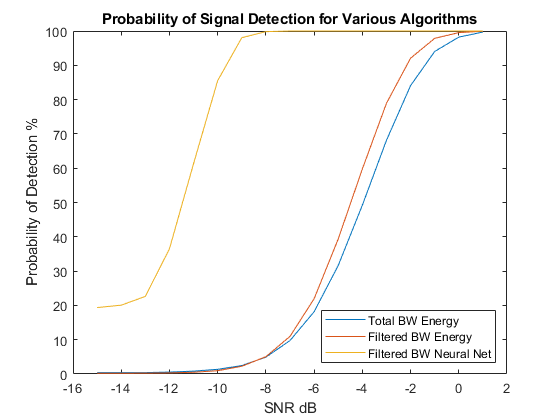

% Plot Results
snr = [-15 -14 -13 -12 -11 -10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1]; % Don't know if this is correct, need to figure out how to set SNR in simulation
plot(snr, P_d_tot_arr)
hold on
plot(snr, P_d_bw_arr)
plot(snr, P_d_nn_arr)
hold off
lgd = legend('Total BW Energy', 'Filtered BW Energy', 'Filtered BW Neural Net', 'Location', 'southeast');
xlabel('SNR dB');
ylabel('Probability of Detection %');
title('Probability of Signal Detection for Various Algorithms');

%pbaspect([2 2 1])

















